# Post-activation Depression - Group data Analysis

*Developed by: Pedro Valadao (pvaladao@tuta.io). *Last Modified: 10/05/2021.

*Last modified: 10/05/21.*

*Sample: 14 CP + 15 TD + 1 SDR case study. *

PAD ratio (Fast/Slow) was calculated using peak to peak H-reflex values normalized by the preceeding M-wave. Since for each participant around 15 values for each condition had to be joined, both median and mean values were utilized. Median calculation is more appropriate since some participants have non-normal distributions. 

**Results: **The relative PAD in the CP group [1.01 (IQR:0.21)] was significantly lower than the TD group [0.63 (IQR:0.51), p = 0.006, Hedge´s g = 0.99, 95%CI = 0.28 to 1.73]. 

- H/Hmax was not statistically different between the TD group [0.78 (0.08)] and the CP group [0.71 (0.18), t(20) = -1.481, p = 0.154, 95%CI = -0.178 to 0.030, power = 0.2, Hedge´s g = 0.51, 95%CI = -0.17 to 1.22].

- M-wave

## Relative PAD ratio (calculated from the medians of the conditions)

Both groups have normally distributed data and equal variances -  Independent t-test was used to compare groups.

### Preparing data/ Group summary

load('PAD_all.mat') %pad relative/absolute + descriptives of: H, M, H/M, H/Hmax and Mmax.
PAD_results_all.Group = categorical(PAD_results_all.Group); %make group a categorical var
PAD_results = PAD_results_all(PAD_results_all.Subject ~= "5105",:); %exclude case study
SDR_PAD = PAD_results_all(PAD_results_all.Subject == "5105",:); %var for case study
groupdata = groupsummary(PAD_results,"Group",{'mean','std','median','min','max','var'},'PAD_relative_median')

groupdata = 2×8 table
    Group    GroupCount    mean_PAD_relative_median    std_PAD_relative_median    median_PAD_relative_median    min_PAD_relative_median    max_PAD_relative_median    var_PAD_relative_median
    _____    __________    ________________________    _______________________    __________________________    _______________________    _______________________    _______________________

     CP          14           0.813281709964712           0.213118621746957           0.817518732731121            0.403195092227097          1.16268165176519          0.0454195469353227   
     TD          15           0.557990155391028           0.335936924105868           0.473682445367958            0.148690436239971   

PAD_re_median_CP = PAD_results.PAD_relative_median(PAD_results.Group == "CP"); %PAD relative median - CP group
PAD_re_median_TD = PAD_results.PAD_relative_median(PAD_results.Group == "TD"); %PAD relative median - TD group

### Kurtosis, Skewness, Normality and Equal variances.

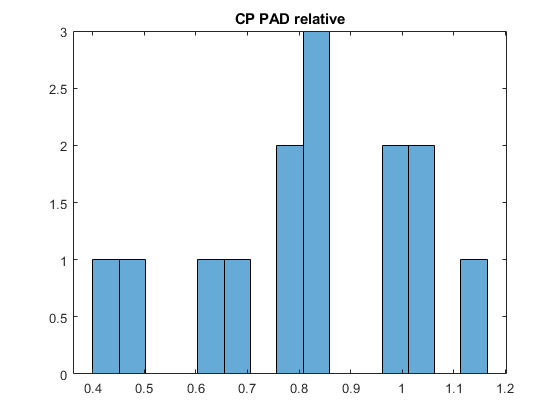

histogram(PAD_re_median_CP,15),title('CP PAD relative')

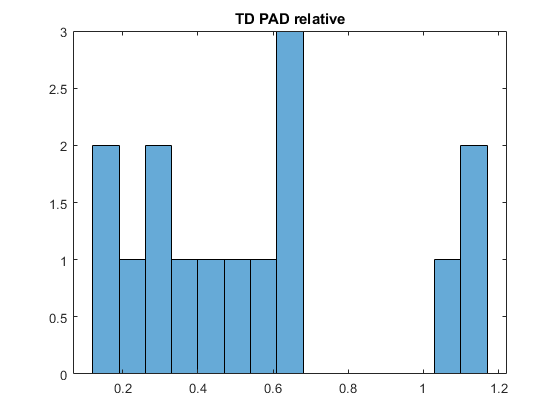

histogram(PAD_re_median_TD,15),title('TD PAD relative')

kurtosis_CP = kurtosis(PAD_re_median_CP)

kurtosis_CP =           2.49535038379158


kurtosis_TD = kurtosis(PAD_re_median_TD)

kurtosis_TD =           2.32602162285731


skewness_CP = skewness(PAD_re_median_CP)

skewness_CP =         -0.361417422915485


skewness_TD = skewness(PAD_re_median_TD)

skewness_TD =          0.699114062341339


normalitytest(PAD_re_median_CP');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5869 	     0.8811                 1 
KS Stephens Modification       0.6210 	     0.1500                 1 
KS Marsaglia Method            0.5869 	     0.8303                 1 
KS Lilliefors Modification     0.1569 	     0.2000                 1 
Anderson-Darling Test          0.2728 	     0.6685                 1 
Cramer- Von Mises Test         0.0446 	     0.5973                 1 
Shapiro-Wilk Test              0.9659 	     0.8181                 1 
Shapiro-Francia Test           0.9677 	     0.7615                 1 
Jarque-Bera Test               0.4533 	     0.7972                 1 
DAgostino & Pearson Test       0.5117 	     0.7743                 1 


normalitytest(PAD_re_median_TD');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7178 	     0.6815                 1 
KS Stephens Modification       0.7566 	     0.1500                 1 
KS Marsaglia Method            0.7178 	     0.6166                 1 
KS Lilliefors Modification     0.1853 	     0.1759                 1 
Anderson-Darling Test          0.6785 	     0.0504                 1 
Cramer- Von Mises Test         0.0957 	     0.1290                 1 
Shapiro-Wilk Test              0.8878 	     0.0621                 1 
Shapiro-Francia Test           0.9024 	     0.0939                 1 
Jarque-Bera Test               1.5058 	     0.4710                 1 
DAgostino & Pearson Test       1.9385 	     0.3794                 1 


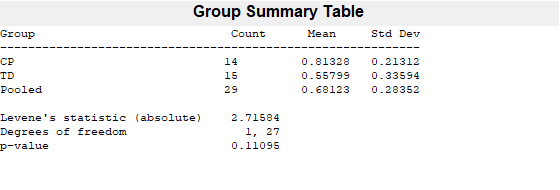

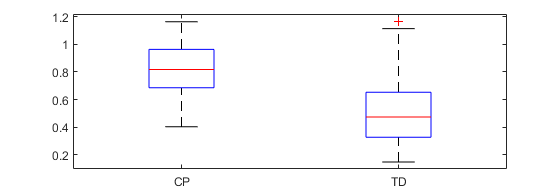

p =          0.110946737996247


p = vartestn(PAD_results.PAD_relative_median,PAD_results.Group,'TestType','LeveneAbsolute')

p = vartestn(PAD_results.PAD_relative_median,PAD_results.Group,'TestType','LeveneQuadratic', 'display','off')

p =         0.0934513326629367


### Indenpendet t-test, Effect Size (Hedge's g).

[h,p,ci,stats] = ttest2(PAD_re_median_TD,PAD_re_median_CP)%independent ttest

h =      1


p =         0.0223725888352644


ci =          -0.47147344965229
       -0.0391096594950777


stats = struct with fields:
    tstat: -2.42302900565985
       df: 27
       sd: 0.283523122569176


stats_PADre_median = mes(PAD_re_median_TD,PAD_re_median_CP,'hedgesg','exactCi',true) %hedge´s g

stats_PADre_median = struct with fields:
            isDep: 0
            nBoot: 0
        confLevel: 0.95
                n: [2×1 double]
                t: [1×1 struct]
          hedgesg: -0.87518028578273
        hedgesgCi: [2×1 double]
    hedgesgCiType: 'exact analytical'


## Relative PAD ratio (calculated from the means of the conditions)

TD is not normally distributed, both groups have equal variances. Same results as when using the medians.

### Group summary

groupdata = groupsummary(PAD_results,"Group",{'mean','std','median','min','max','var'},'PAD_relative')

groupdata = 2×8 table
    Group    GroupCount    mean_PAD_relative    std_PAD_relative     median_PAD_relative    min_PAD_relative     max_PAD_relative     var_PAD_relative 
    _____    __________    _________________    _________________    ___________________    _________________    ________________    __________________

     CP          14        0.799912888861616    0.207526420947254     0.798260175400902     0.428445848700591    1.15932443763763    0.0430672153911769
     TD          15        0.563260980714421    0.325108377028419     0.476535410686468     0.179440235985857    1.15740474530249     0.105695456814052


PAD_re_CP = PAD_results.PAD_relative(PAD_results.Group == "CP"); %PAD relative CP group
PAD_re_TD = PAD_results.PAD_relative(PAD_results.Group == "TD"); %PAD relative TD group

### Kurtosis, Skewness, Normality and Equal variances.

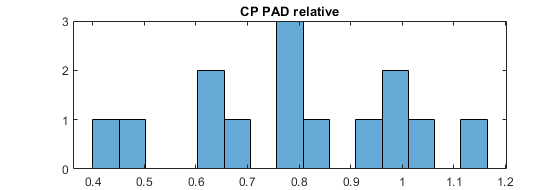

histogram(PAD_re_CP,15),title('CP PAD relative')

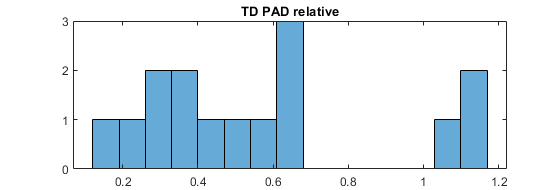

histogram(PAD_re_TD,15),title('TD PAD relative')

kurtosis_CP = kurtosis(PAD_re_CP)

kurtosis_CP =           2.27965347155924


kurtosis_TD = kurtosis(PAD_re_TD)

kurtosis_TD =           2.38363716555247


skewness_CP = skewness(PAD_re_CP)

skewness_CP =         -0.173716053199338


skewness_TD = skewness(PAD_re_TD)

skewness_TD =          0.767287766409639


normalitytest(PAD_re_CP');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4128 	     0.9956                 1 
KS Stephens Modification       0.4367 	     0.1500                 1 
KS Marsaglia Method            0.4128 	     0.9883                 1 
KS Lilliefors Modification     0.1103 	     0.2000                 1 
Anderson-Darling Test          0.1874 	     0.9037                 1 
Cramer- Von Mises Test         0.0267 	     0.8875                 1 
Shapiro-Wilk Test              0.9773 	     0.9563                 1 
Shapiro-Francia Test           0.9814 	     0.9540                 1 
Jarque-Bera Test               0.3731 	     0.8298                 1 
DAgostino & Pearson Test       0.1907 	     0.9091                 1 


normalitytest(PAD_re_TD');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7487 	     0.6293                 1 
KS Stephens Modification       0.7892 	     0.1339                 1 
KS Marsaglia Method            0.7487 	     0.5646                 1 
KS Lilliefors Modification     0.1933 	     0.1364                 1 
Anderson-Darling Test          0.7306 	     0.0401                 0 
Cramer- Von Mises Test         0.1043 	     0.0982                 1 
Shapiro-Wilk Test              0.8785 	     0.0451                 0 
Shapiro-Francia Test           0.8932 	     0.0700                 1 
Jarque-Bera Test               1.7093 	     0.4254                 1 
DAgostino & Pearson Test       2.2598 	     0.3231                 1 


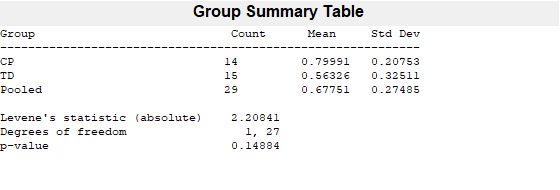

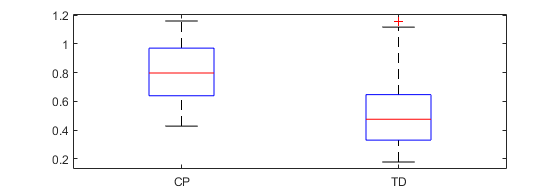

p =          0.148844430963872


p = vartestn(PAD_results.PAD_relative,PAD_results.Group,'TestType','LeveneAbsolute')

p = vartestn(PAD_results.PAD_relative,PAD_results.Group,'TestType','LeveneQuadratic', 'display','off')

p =         0.0991277184856595


### Independent t-test, Effect Size (Hedge's g).

[p,h,stats] = ranksum(PAD_re_TD,PAD_re_CP, 'method','exact') %Wilcoxon rank sum test, exact p calculation

p =         0.0178435550026844


h = logical
   1


stats = struct with fields:
    ranksum: 171


## Test control variables

#### H/Hmax in slow condition

The stimulation intensity was adjusted to evoke H-reflex values during the slow condition on the ascending limb of the recruitment curve (75%Hmax (i.e., H/Hmax).

TD group does not have normally distributed data. Both groups have equal variances. The median was use to summarize each subject's data due to high cv in some subjetcs. Wilcoxon rank sum test was used.

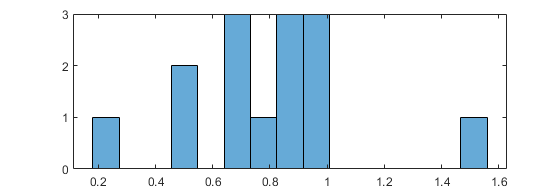

descriptive_all.cv_H_Hmax = descriptive_all.std_H_Hmax./descriptive_all.mean_H_Hmax; % add cv col
descriptive_all.Group = categorical(descriptive_all.Group);%make group a categorical var
descriptive_all.Condition = categorical(descriptive_all.Condition);%make condition a categorical var
descriptives = descriptive_all(descriptive_all.Subject ~= "5105",:); %exclude SDR
Slow_data = descriptives(descriptives.Condition == "Slow",:); % all data in the slow condition
H_Hmax_CP = Slow_data.median_H_Hmax(Slow_data.Group == "CP",:); % cp data
H_Hmax_TD = Slow_data.median_H_Hmax(Slow_data.Group == "TD",:); % td data
histogram(H_Hmax_CP,15), 

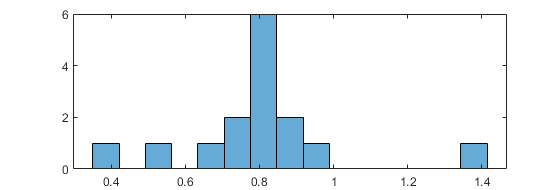

histogram(H_Hmax_TD,15), 

normalitytest(H_Hmax_CP');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7609 	     0.6089                 1 
KS Stephens Modification       0.8050 	     0.1159                 1 
KS Marsaglia Method            0.7609 	     0.5423                 1 
KS Lilliefors Modification     0.2033 	     0.1209                 1 
Anderson-Darling Test          0.5767 	     0.1342                 1 
Cramer- Von Mises Test         0.0893 	     0.1573                 1 
Shapiro-Wilk Test              0.9185 	     0.2089                 1 
Shapiro-Francia Test           0.8902 	     0.0747                 1 
Jarque-Bera Test               1.8948 	     0.3878                 1 
DAgostino & Pearson Test       4.6960 	     0.0956                 1 


normalitytest(H_Hmax_TD');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9563 	     0.3198                 1 
KS Stephens Modification       1.0081 	     0.0201                 0 
KS Marsaglia Method            0.9563 	     0.2720                 1 
KS Lilliefors Modification     0.2469 	     0.0144                 0 
Anderson-Darling Test          1.0709 	     0.0090                 0 
Cramer- Von Mises Test         0.1876 	     0.0077                 0 
Shapiro-Wilk Test              0.8498 	     0.0173                 0 
Shapiro-Francia Test           0.8129 	     0.0068                 0 
Jarque-Bera Test               7.3426 	     0.0254                 0 
DAgostino & Pearson Test       10.0504 	     0.0066                 0 


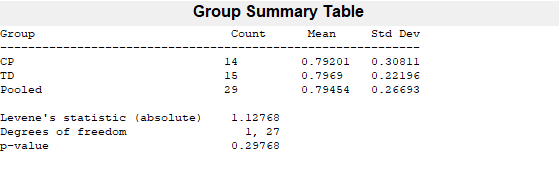

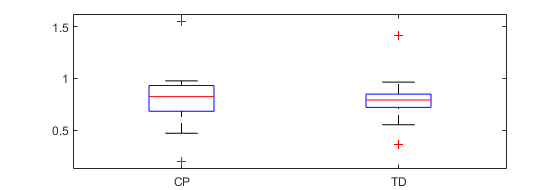

p =            0.2976764133645


p = vartestn(Slow_data.median_H_Hmax,Slow_data.Group,'TestType','LeveneAbsolute')

p = vartestn(Slow_data.median_H_Hmax,Slow_data.Group,'TestType','LeveneQuadratic', 'display','off')

p =           0.42587848917838


[p,h,stats] = ranksum(H_Hmax_CP,H_Hmax_TD, 'method','exact') %Wilcoxon rank sum test, exact p calculation

p =          0.846694170974368


h = logical
   0


stats = struct with fields:
    ranksum: 215


%pwrout = sampsizepwr('t2',[0.794,0.208],0.764,[],16, "Ratio",1.0625) 
%stats_H_Hmax = mes(H_Hmax_TD,H_Hmax_CP,'hedgesg','exactCi',true)
median(H_Hmax_CP)

ans =          0.824602115298119


iqr(H_Hmax_CP)

ans =          0.248476069075496


median(H_Hmax_TD)

ans =          0.791102811170532


iqr(H_Hmax_TD)

ans =          0.128885974317367


#### Preceeding M-wave normlized by Mmax (M/Mmax)

The preceeding M-wave is a good indicator of the effective stimulation intensity, so the 75%Hmax target was chosen to ensure that there would be a preceding M-wave. Ideally, M/Mmax should be the same between both conditions (fast vs. slow), otherwise it would affect the H-reflex response. 

None of the 4 data vectors (2 Groups * 2 Conditions) is normally distributed. Both test pairs (CP slow vs. Fast/ TD slow vs. Fast) have equal variances. The median was used to summarize each subject's data because some subjects had very high CV.  Wilcoxon signed rank test (non parametric analog of paired t test) was used to check differences between grand medians. 

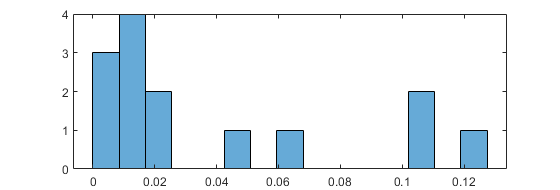

descriptives.cv_Mwave = descriptives.std_M_wave./descriptives.mean_M_wave; % add cv col
CP_data = descriptives(descriptives.Group == "CP",:); %data divided in groups
TD_data = descriptives(descriptives.Group == "TD",:);
M_Mmax_CP_Fast = CP_data.median_M_wave(CP_data.Condition == "Fast")./CP_data.Mmax(CP_data.Condition == "Fast"); % data divided in conditions
M_Mmax_CP_Slow = CP_data.median_M_wave(CP_data.Condition == "Slow")./CP_data.Mmax(CP_data.Condition == "Slow"); 
M_Mmax_TD_Fast = TD_data.median_M_wave(TD_data.Condition == "Fast")./TD_data.Mmax(TD_data.Condition == "Fast");
M_Mmax_TD_Slow = TD_data.median_M_wave(TD_data.Condition == "Slow")./TD_data.Mmax(TD_data.Condition == "Slow");
histogram(M_Mmax_CP_Fast,15), 

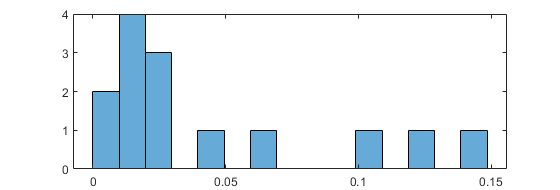

histogram(M_Mmax_CP_Slow,15), 

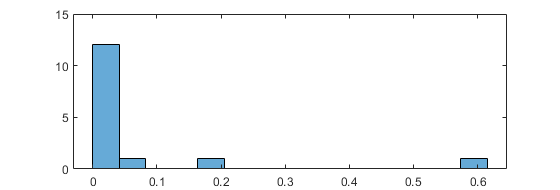

histogram(M_Mmax_TD_Fast,15), 

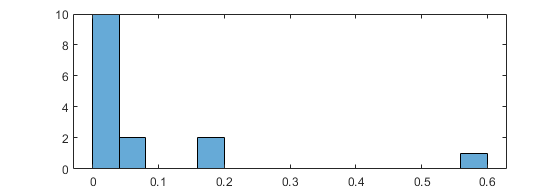

histogram(M_Mmax_TD_Slow,15), 

normalitytest(M_Mmax_CP_Fast');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.1549 	     0.1388                 1 
KS Stephens Modification       1.2219 	     0.0100                 0 
KS Marsaglia Method            1.1549 	     0.1109                 1 
KS Lilliefors Modification     0.3086 	     0.0008                 0 
Anderson-Darling Test          1.3893 	     0.0022                 0 
Cramer- Von Mises Test         0.2461 	     0.0014                 0 
Shapiro-Wilk Test              0.7909 	     0.0039                 0 
Shapiro-Francia Test           0.8015 	     0.0065                 0 
Jarque-Bera Test               2.5793 	     0.2754                 1 
DAgostino & Pearson Test       3.5892 	     0.1662                 1 


normalitytest(M_Mmax_CP_Slow');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.2110 	     0.1064                 1 
KS Stephens Modification       1.2813 	     0.0100                 0 
KS Marsaglia Method            1.2110 	     0.0834                 1 
KS Lilliefors Modification     0.3237 	     0.0003                 0 
Anderson-Darling Test          1.5710 	     0.0010                 0 
Cramer- Von Mises Test         0.2859 	     0.0005                 0 
Shapiro-Wilk Test              0.7672 	     0.0020                 0 
Shapiro-Francia Test           0.7719 	     0.0032                 0 
Jarque-Bera Test               3.4105 	     0.1817                 1 
DAgostino & Pearson Test       5.2946 	     0.0708                 1 


normalitytest(M_Mmax_TD_Fast');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.5263 	     0.0190                 0 
KS Stephens Modification       1.6088 	     0.0100                 0 
KS Marsaglia Method            1.5263 	     0.0130                 0 
KS Lilliefors Modification     0.3941 	     0.0000                 0 
Anderson-Darling Test          3.7965 	     0.0000                 0 
Cramer- Von Mises Test         0.7286 	     0.0000                 0 
Shapiro-Wilk Test              0.4413 	     0.0000                 0 
Shapiro-Francia Test           0.4122 	     0.0000                 0 
Jarque-Bera Test               67.5760 	     0.0000                 0 
DAgostino & Pearson Test       35.8510 	     0.0000                 0 


normalitytest(M_Mmax_TD_Slow'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.3954 	     0.0407                 0 
KS Stephens Modification       1.4708 	     0.0100                 0 
KS Marsaglia Method            1.3954 	     0.0300                 0 
KS Lilliefors Modification     0.3603 	     0.0000                 0 
Anderson-Darling Test          3.1130 	     0.0000                 0 
Cramer- Von Mises Test         0.5773 	     0.0000                 0 
Shapiro-Wilk Test              0.5170 	     0.0000                 0 
Shapiro-Francia Test           0.4916 	     0.0000                 0 
Jarque-Bera Test               49.5282 	     0.0000                 0 
DAgostino & Pearson Test       31.4849 	     0.0000                 0 


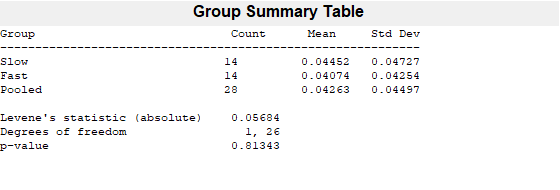

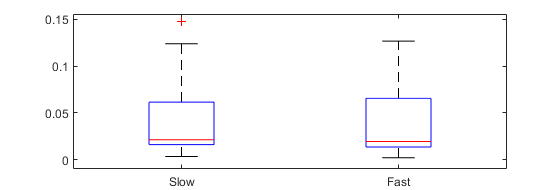

p =          0.813425259889606


p = vartestn(CP_data.median_M_wave./CP_data.Mmax,CP_data.Condition,'TestType','LeveneAbsolute'),

p = vartestn(CP_data.median_M_wave./CP_data.Mmax,CP_data.Condition,'TestType','LeveneQuadratic','display','off'),

p =          0.690577846758773


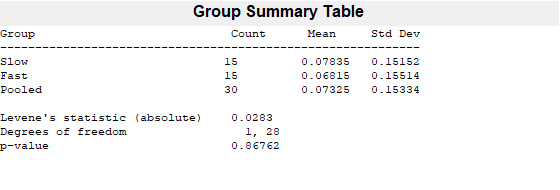

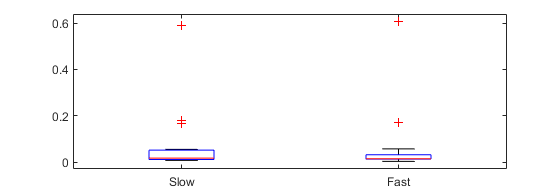

p =          0.867621292326511


p = vartestn(TD_data.median_M_wave./TD_data.Mmax,TD_data.Condition,'TestType','LeveneAbsolute'),

p = vartestn(TD_data.median_M_wave./TD_data.Mmax,TD_data.Condition,'TestType','LeveneQuadratic','display','off'),

p =          0.968258352999478


[p,h,stats] = signrank(M_Mmax_CP_Fast,M_Mmax_CP_Slow, 'method','exact') %Wilcoxon signed rank test (paired samples), exact p calculation

p =            0.1937255859375


h = logical
   0


stats = struct with fields:
    signedrank: 31


[p,h,stats] = signrank(M_Mmax_TD_Fast,M_Mmax_TD_Slow, 'method','exact') %Wilcoxon signed rank test (paired samples), exact p calculation

p =                0.638671875


h = logical
   0


stats = struct with fields:
    signedrank: 51


median(M_Mmax_CP_Fast)

ans =         0.0193203305803061


iqr(M_Mmax_CP_Fast)

ans =         0.0519897309169661


median(M_Mmax_CP_Slow)

ans =         0.0212252954887807


iqr(M_Mmax_CP_Slow)

ans =         0.0453043449787498


median(M_Mmax_TD_Fast)

ans =         0.0150371287388706


iqr(M_Mmax_TD_Fast)

ans =          0.018568776452163


median(M_Mmax_TD_Slow)

ans =         0.0175185757594216


iqr(M_Mmax_TD_Slow)

ans =         0.0405682583890878


#### Correlation between H-reflex and PAD. 

load("Recruitment_all.mat")
H_results = H_all(H_all.Subject ~= "5105",:); %exclude SDR
CP_HM = H_results.Hmax_Mmax(H_results.Group == 'CP');
TD_HM = H_results.Hmax_Mmax(H_results.Group == 'TD');
[r p] = corr(PAD_re_median_CP,CP_HM)

r =          0.418813020671313


p =          0.136096816030092


R2 = r^2

R2 =           0.17540434628383


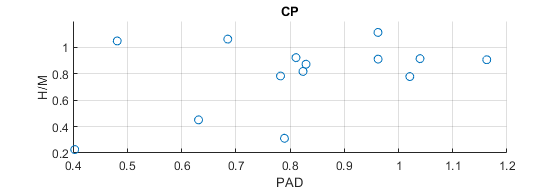

scatter(PAD_re_median_CP,CP_HM), title('CP'),xlabel('PAD'),ylabel('H/M'),grid on

[r p] = corr(PAD_re_median_TD,TD_HM)

r =         -0.372939186166155


p =          0.170972297332675


R2 = r^2

R2 =          0.139083636578274


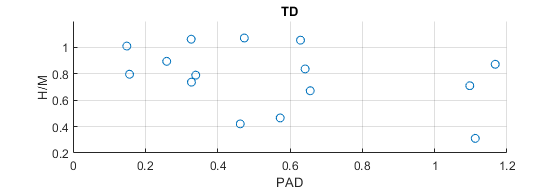

scatter(PAD_re_median_TD,TD_HM), title('TD'),xlabel('PAD'),ylabel('H/M'),,grid on